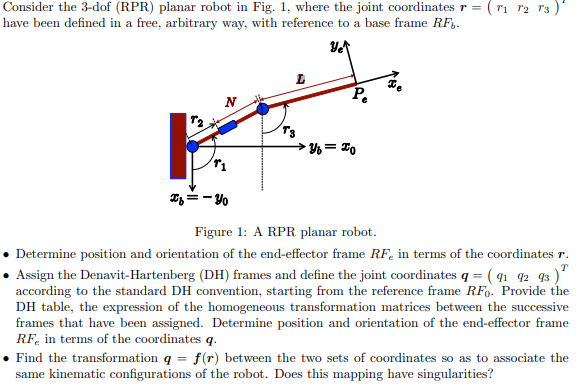

% clear all, close all, clc
% syms A B C D q1 q2
% Njoints=3;
% q=sym('q',[Njoints,1]);
% L_=3
% d1_=1;
% d2_=1;
% syms alpha beta gamma L
% 
% a1=A
% a2=6
% dhTable=[pi/2,0,0,q(1);
%          -pi/2,0,q(2),0;
%          0,L,0,q(3)
%          ];
% links = [
%     Revolute('alpha', pi/2, 'a', 0 ,'d', 0);
%     Prismatic('qlim', [0 5],'alpha',-pi/2,'theta',0);
%     Revolute('alpha',  0, 'a', L_,'d', 0);
%     ];
% c600 = SerialLink(links);
% c600.teach([pi/2 ,L_,0],'view','x')
% [T_total T_Partial,RTotal,RPartial,PTotal, PPartial] = getTransformationMatrix(dhTable, 'alpha');

% PTotal
% syms N real;
% syms L real;
% r=sym('r',[3,1],'real');
% q_r=[r(1),r(2)+N,r(3)-r(1)-pi/2]'
% PTotal_r=simplify(subs(PTotal,q,q_r))
% r_q=simplify(q_r==q)

Exercise 3

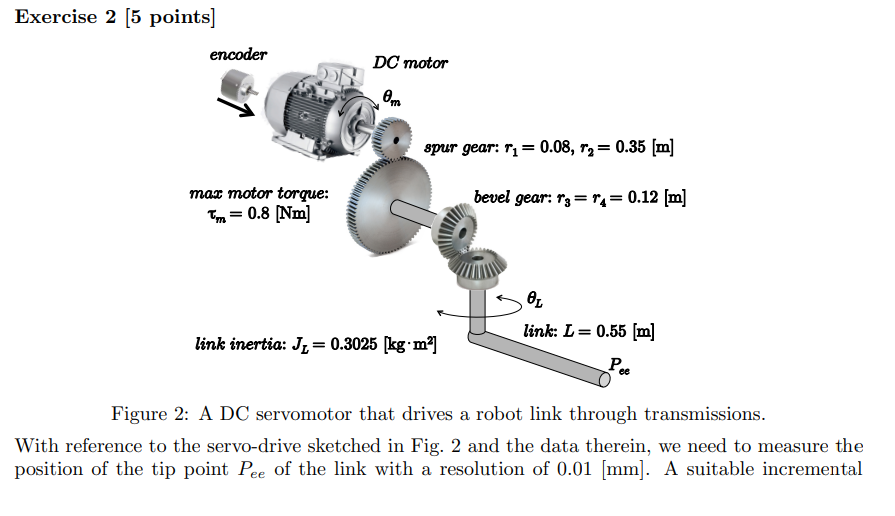

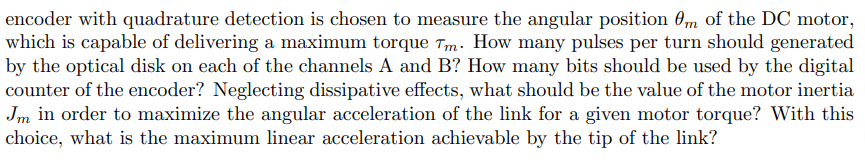

exercise 3

% clear all, close all, clc
% syms A B C D q1 q2
% Njoints=3;
% q=sym('q',[Njoints,1]);
% L_=3
% d1_=1;
% d2_=1;
% syms alpha beta gamma L
% 
% a1=A
% a2=6
% dhTable=[pi/2,0,0,q(1);
%          -pi/2,0,q(2),0;
%          0,L,0,q(3)
%          ];
% links = [
%     Revolute('alpha', pi/2,'a', 150,'d', 550)
% %     Prismatic('qlim', [0 5],'alpha',-pi/2,'theta',0);
%      Revolute('alpha',  0,      'a', 825,'d', 0);
%      Revolute('alpha',  pi/2,   'a', 0,'d', 0);
%      Revolute('alpha',  pi/2,   'a', 0,'d', 625);
%      Revolute('alpha', -pi/2,   'a', 0,'d', 0);
%      Revolute('alpha',  0,      'a', 0,'d', 110);
% 
%     ];
% c600 = SerialLink(links);
% c600.teach([0,pi/2,pi/2,pi,0,0],'view','x')

Exercise 4

r=sym('r',[3,1]);
angle=sym('theta');

A_R_B=getRotAroundVector(r,angle)

$$A\_R\_B = \begin{array}{l} \left(\begin{array}{ccc} {r_{1}}^{2}-\cos\left(\theta \right)\,\left({r_{1}}^{2}-1\right) & r_{1}\,r_{2}-r_{3}\,\sin\left(\theta \right)-\sigma_{3} & r_{1}\,r_{3}+r_{2}\,\sin\left(\theta \right)-\sigma_{2}\\ r_{1}\,r_{2}+r_{3}\,\sin\left(\theta \right)-\sigma_{3} & {r_{2}}^{2}-\cos\left(\theta \right)\,\left({r_{2}}^{2}-1\right) & r_{2}\,r_{3}-r_{1}\,\sin\left(\theta \right)-\sigma_{1}\\ r_{1}\,r_{3}-r_{2}\,\sin\left(\theta \right)-\sigma_{2} & r_{2}\,r_{3}+r_{1}\,\sin\left(\theta \right)-\sigma_{1} & {r_{3}}^{2}-\cos\left(\theta \right)\,\left({r_{3}}^{2}-1\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=r_{2}\,r_{3}\,\cos\left(\theta \right)\\ \sigma_{2}=r_{1}\,r_{3}\,\cos\left(\theta \right)\\ \sigma_{3}=r_{1}\,r_{2}\,\cos\left(\theta \right) \end{array}$$

% DHMatrix = getDHSymMatrix()
o_R_A_=[3/4,sqrt(3/8), -1/4;
        -sqrt(3/8),1/2,-sqrt(3/8);
        -1/4,sqrt(3/8), 3/4]

o_R_A_ =     0.7500    0.6124   -0.2500
   -0.6124    0.5000   -0.6124
   -0.2500    0.6124    0.7500


A_R_0_=o_R_A_'

A_R_0_ =     0.7500   -0.6124   -0.2500
    0.6124    0.5000    0.6124
   -0.2500   -0.6124    0.7500


o_R_B_=[sqrt(1/2),0, -sqrt(1/2);
        0,1,0;
        sqrt(1/2),0,sqrt(1/2)]

o_R_B_ =     0.7071         0   -0.7071
         0    1.0000         0
    0.7071         0    0.7071


    A_R_B_=A_R_0_*o_R_B_

A_R_B_ =     0.3536   -0.6124   -0.7071
    0.8660    0.5000         0
    0.3536   -0.6124    0.7071


    R_r_theta_=solve(A_R_B==A_R_B_)

R_r_theta_ = struct with fields:
       r1: [2×1 sym]
       r2: [2×1 sym]
       r3: [2×1 sym]
    theta: [2×1 sym]


    theta_=-73.72*pi/180;
    
    r_=[0.3190;0.5525;-0.7701];
    
A_R_B2=subs(A_R_B,r,r_);
digits(5)
A_R_B2=vpa(subs(A_R_B2,angle,theta_))

$$A\_R\_B2 = \left(\begin{array}{ccc} 0.35357 & -0.61238 & -0.70714\\ 0.86606 & 0.50001 & 4.4556e-6\\ 0.35355 & -0.61241 & 0.70713 \end{array}\right)$$